addpath('rawData\data_1\')

load('rawData\data_1\data_1.mat');

%暂时先只处理0.01s。别忘了最终是要处理整个文件的！
seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;
fs=f_s;

### Task 1

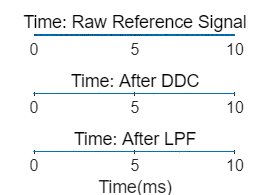

y1rd=sigAfterDDC(seq_ref1,fs);
y1rf=sigAfterLPF(seq_ref1,fs);
plotTimeSig(seq_ref1,fs,1,3,'Time: Raw Reference Signal')
plotTimeSig(y1rd,fs,2,3,'Time: After DDC')
plotTimeSig(y1rf,fs,3,3,'Time: After LPF')

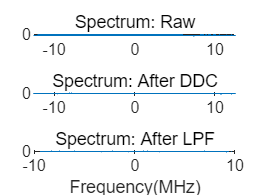


plotSpectrum(seq_ref1,fs,1,3,'Spectrum: Raw')
plotSpectrum(y1rd,fs,2,3,'Spectrum: After DDC')
plotSpectrum(y1rf,fs,3,3,'Spectrum: After LPF')


y1sf=sigAfterLPF(seq_sur1,fs);

### Task 2

disp(['最大可能时延：',num2str(300/3e8)])

最大可能时延：1e-06


disp(['最大可能频移：',num2str(10*2123e6/3e8)])

最大可能频移：70.7667



$$\tau_{\max } =\frac{2D}{c}$$



$$f_{D,\max } =v_{\max } \cdot \frac{f_s }{c}$$


Success


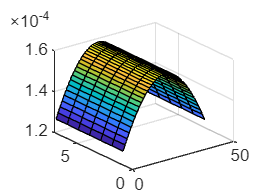

cor(1e-7,-40,y1sf,y1rf,fs)
cor(1e-7,40,y1sf,y1rf,fs)
cor(1e-7,0,y1sf,y1rf,fs)

corMat=zeros(7,41);
tau=linspace(0,1/fs*6,7);
fd=linspace(-40,40,41).*6;
for i=1:7
    for j=1:41
        corMat(i,j)=cor(tau(i),fd(j),y1sf,y1rf,fs);
    end
end
disp('Success')

Success


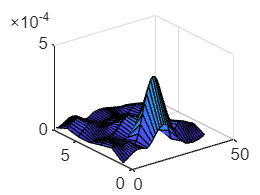

figure
surf(corMat)

Mat=[1,2,3,4,5;6,7,8,9,10];
surf(Mat)

tic
Cor=corVar(1/fs,40,y1sf,y1rf,'dot')

Cor = 3.3435e-04

toc

历时 0.017729 秒。


tic
Cor=corVar(1/fs,40,y1sf,y1rf,25000000,'for')

Cor = 3.3435e-04

toc

历时 0.058800 秒。


function Cor=cor(tau,fd,y_surv,y_ref,fs)
    zero_compensation =zeros(1,fix(tau*fs));
    y_surv=[y_surv,zero_compensation];
    y_ref=[zero_compensation,y_ref];
    
    % Ncomp=fix(tau*fs);
    % y_surv=y_surv(1+Ncomp:end);
    % y_ref=y_ref(1:(end-Ncomp));

    % Cor=0;
    % for k=1:length(y_surv)
    %     Cor=Cor+y_surv(k)*conj(y_ref(k))*exp(-2j*pi*fd*k/fs);
    % end
    function y=exp_component(n,fd,fs)
        y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
    end
    Cor=abs(sum(y_surv.*conj(y_ref).*exp_component(length(y_surv),fd,fs)));
end

function Cor=corVar(tau,fd,y_surv,y_ref,varargin)
    numArg=nargin-4;
    %varagin: 'method', fs

    fs=25000000;
    Type='fft';%这是默认采样率和算法

    for i=1:numArg
        if isnumeric(varargin{i})
            fs=varargin{i};
        elseif ischar(varargin{i})
            Type=varargin{i};
        end
    end

    
    zero_compensation=zeros(1,fix(tau*fs));
    y_surv=[y_surv,zero_compensation];
    y_ref=[zero_compensation,y_ref];

    if strcmp(Type,'fft')

    elseif strcmp(Type,'dot')
        Cor=abs(sum(y_surv.*conj(y_ref).*exp_component(length(y_surv),fd,fs)));
    elseif strcmp(Type,'for')
        Cor=0;
        for k=1:length(y_surv)
            Cor=Cor+y_surv(k)*conj(y_ref(k))*exp(-2j*pi*fd*k/fs);
        end
        Cor=abs(Cor);
    else
        disp('Invalid method name.')
        return;
    end
end

function y=exp_component(n,fd,fs)
    y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
end

Basical function

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function plotTimeSig(x,fs,a,n,Title)
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,real(x)),title(Title)
    ylabel("Amplitude"),ylim([-1e-3,1e-3])%注意这里的ylim和PPT不一样
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),title(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end

Task 1 function: DDC and filter

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;
    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end